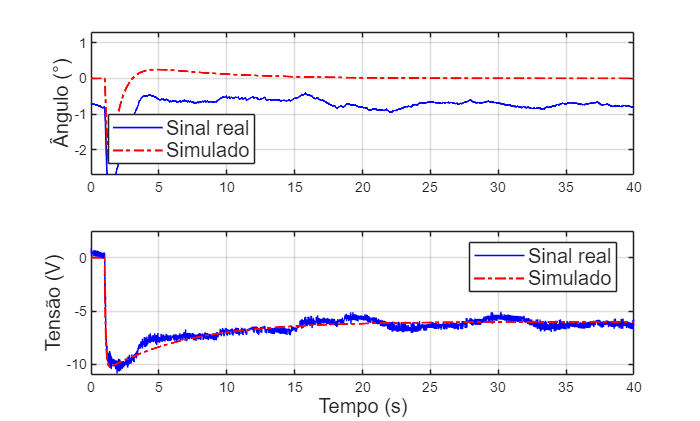

clc;
close all;

% Carregar dados do arquivo
data = load('dados2.txt');
% data2 = load('dados4.txt');

% Definir intervalo de tempo
inicio = 1;
final = 4000;

xInit = 0;
xFinal = 40;


tempo = data(inicio:final, 1)-60;
angulo1 = data(inicio:final, 2)*57.296; % theta
angulo2 = data(inicio:final, 3)*57.296; % theta_dot
angulo3 = data(inicio:final, 4)*57.296; % omega
entrada = data(inicio:final, 5); % Ação de controle
disturbio = data(inicio:final, 6); % Disturbio

% angulo1_ordem2 = data2(inicio:final, 2)*57.296; % theta
% angulo2_ordem2 = data2(inicio:final, 3)*57.296; % theta_dot
% angulo3_ordem2 = data2(inicio:final, 4)*57.296; % omega
% entrada_ordem2 = data2(inicio:final, 5); % Ação de controle
% disturbio_ordem2 = data2(inicio:final, 6); % Disturbio

% Dados do Simulink
tempo_sim = out.tout;
angulo1_sim = out.yout{1}.Values.Data; % theta
angulo2_sim = out.yout{2}.Values.Data; % theta_dot
angulo3_sim = out.yout{3}.Values.Data*57.296; % omega
entrada_sim = out.yout{4}.Values.Data; % Ação de controle
disturbio_sim = out.yout{5}.Values.Data; % Disturbio

figure;
subplot(2, 1, 1)
plot(tempo, angulo1 - 0.065, 'b', 'LineWidth', 1);
hold on;
% plot(tempo, angulo1_ordem2 + 0.11, '--g', 'LineWidth', 1.1);
plot(tempo_sim, angulo1_sim, '-.r', 'LineWidth', 1.3);
%xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Ângulo (°)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-2.7 1.3]);
hold off;

subplot(2, 1, 2)
plot(tempo, entrada, 'b', 'LineWidth', 0.5);
hold on;
% plot(tempo, entrada_ordem2, '--g', 'LineWidth', 1.1);
plot(tempo_sim, entrada_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Tensão (V)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-11 2.5]);
hold off;

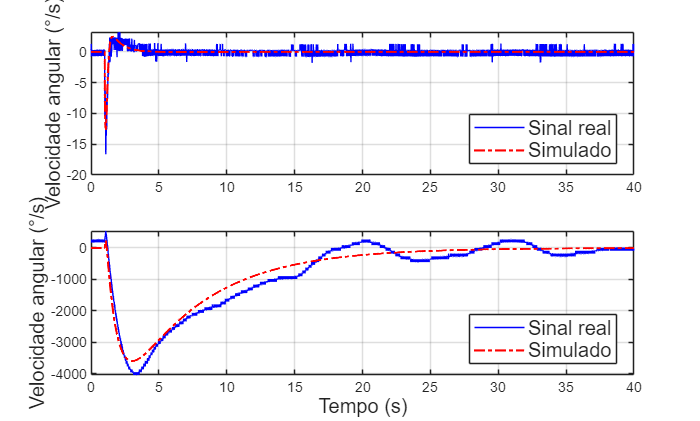


figure;
subplot(2, 1, 1)
plot(tempo, angulo2, 'b', 'LineWidth', 0.5);
hold on;
% plot(tempo, angulo2_ordem2, '--g', 'LineWidth', 1.1);
plot(tempo_sim, angulo2_sim, '-.r', 'LineWidth', 1.3);
%xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Velocidade angular (°/s)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
hold off;

subplot(2, 1, 2)
plot(tempo, angulo3, 'b', 'LineWidth', 0.5);
hold on;
% plot(tempo, angulo3_ordem2, '--g', 'LineWidth', 1.1);
plot(tempo_sim, angulo3_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Velocidade angular (°/s)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
hold off;

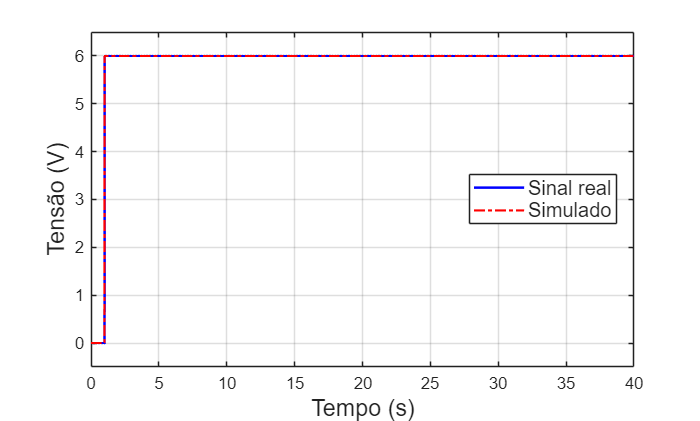


figure;
plot(tempo, disturbio, 'b', 'LineWidth', 1.5);
hold on;
plot(tempo_sim, disturbio_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Tensão (V)', 'FontSize', 14)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-0.5 6.5]);
hold off;